Cleaning the workspace

clearvars
global options

Defining the configurations

%% Defining the configurations (all same structure)
configs = [ 
    struct('mm','sgdm',   'lr',0.19892,'mb',286,'dr',24,'mo',0.85978,'lrdf',0.6384,'l2',0.00099032,'vp',40),...
    struct('mm','sgdm',   'lr',0.19892,'mb',286,'dr',12,'mo',0.85978,'lrdf',0.6384,'l2',0.00099032,'vp',40),...
    struct('mm','sgdm',   'lr',0.19892,'mb',256,'dr',12,'mo',0.85978,'lrdf',0.6384,'l2',0.00099032,'vp',40),...
    struct('mm','sgdm',   'lr',0.19892,'mb',286,'dr',12,'mo',0.85978,'lrdf',0.6384,'l2',2*0.00099032,'vp',40),...
];


Loading Training data

loadtrainingdata

Setting the Layer Setup

co = 18;
numRuns = length(configs);
accTest = zeros(numRuns+2,1);
macroPrecisionTest = zeros(numRuns+2,1);
macroRecallTest = zeros(numRuns+2,1);
macroF1Test = zeros(numRuns+2,1);

Looping through different configurations

for expNum = 1:numRuns
    fprintf('\n=== Running Experiment %d ===\n', expNum);


Cleaning the workspace from previous expirements

    clearvars -except configs co mm  ...
        options expNum ...
        trainImages valImages testImages ...
        trainLabels valLabels testLabels ...
        imageAugmenter trainDS valDS testDS 

setting up the variables used

    cfg = configs(expNum)
    mm = cfg.mm;

displaying the configuration for tracking

    disp(cfg)

setting up the training options

vf = floor(trainDS.NumObservations/cfg.mb);    
createTrainingOptions(cfg.mm,cfg.lr,cfg.dr,150,cfg.mb,valDS,vf,cfg.mo,1,cfg.lrdf,cfg.l2,cfg.vp);

    setting up the layers

    Resnet18

    runing the test

    runfile

calculating metrics

    accTest(expNum)            = acc*100
    macroPrecisionTest(expNum) =  macroPrecision*100
    macroRecallTest(expNum)    = macroRecall*100
    macroF1Test(expNum)        = macroF1*100

    figCM = figure('Name',sprintf('Run %d Confusion Matrices', expNum),'NumberTitle','off');
    set(figCM, 'Position', [100 100 4000 12000]);  % wide layout: 3 subplots side by side

     Training 

    subplot(1,3,1);
    YPredTrain = classify(net, trainDS);
    YTrain = trainLabels;
    cmTrain = confusionmat(YTrain, YPredTrain);
    confusionchart(cmTrain);
    trainAcc = mean(YPredTrain == YTrain);
    title(sprintf('Training CM (Run %d),acc = %.3f %%', expNum,trainAcc*100));


     Validation 

    subplot(1,3,2);  
    YPredVal = classify(net, valDS);
    YVal = valLabels;
    cmVal = confusionmat(YVal, YPredVal);
    confusionchart(cmVal);
    valAcc = mean(YPredVal(:) == YVal(:));
    title(sprintf('Validation CM (Run %d),acc = %.3f %%', expNum,valAcc*100));


      Test 

    subplot(1,3,3);
    YPredTest = classify(net, testDS);
    YTest = testLabels;
    cmTest = confusionmat(YTest, YPredTest);
    confusionchart(cmTest);
    title(sprintf('Testing CM (Run %d),acc = %.3f %%', expNum,acc*100));


Save high-resolution PNG and PDF


=== Running Experiment 1 ===


cfg = struct with fields:
      mm: 'sgdm'
      lr: 0.1989
      mb: 286
      dr: 24
      mo: 0.8598
    lrdf: 0.6384
      l2: 9.9032e-04
      vp: 40


      mm: 'sgdm'
      lr: 0.1989
      mb: 286
      dr: 24
      mo: 0.8598
    lrdf: 0.6384
      l2: 9.9032e-04
      vp: 40




=== Running Training 1 ===

=== Done Training 1 ===


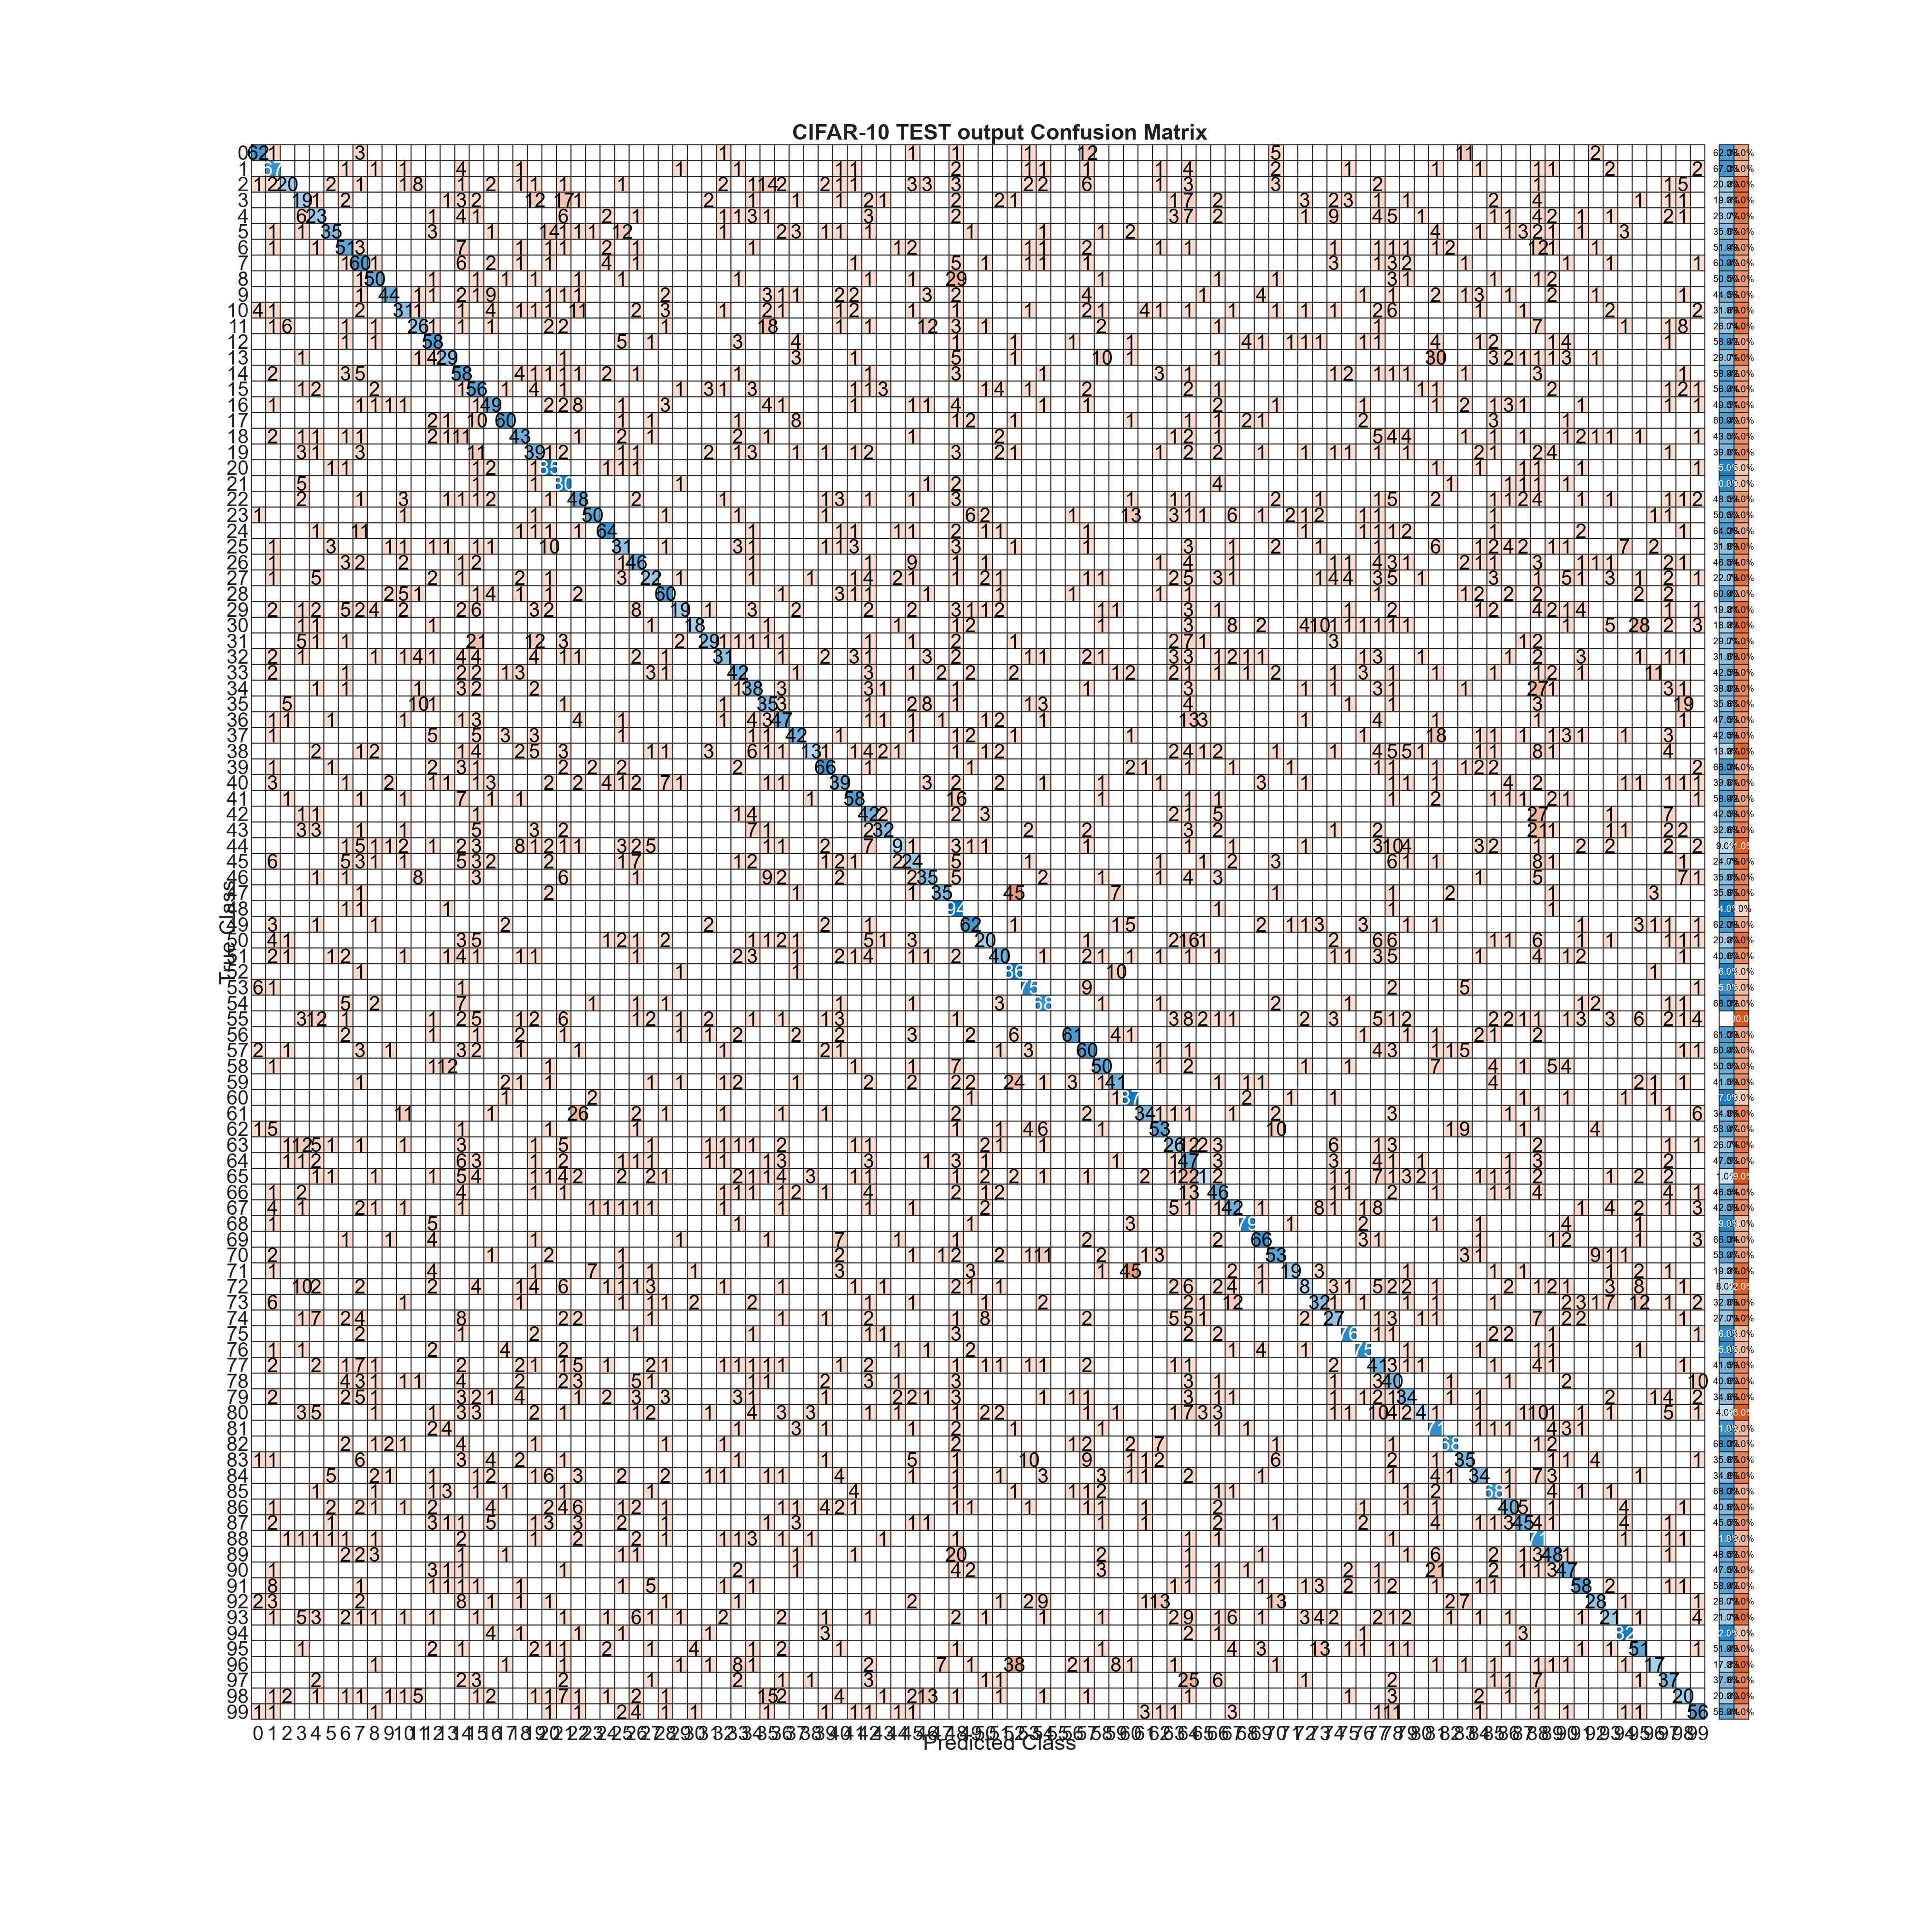

    exportgraphics(figCM, fullfile(outputFolder, sprintf('ConfusionMatrices_Run%d.png',expNum)), 'Resolution', 300);
    exportgraphics(figCM, fullfile(outputFolder, sprintf('ConfusionMatrices_Run%d.pdf',expNum)), 'Resolution', 300);
end

Calculating the mean and Standard deviation

accTest(numRuns+1)            =   mean(accTest(1:numRuns));
macroPrecisionTest(numRuns+1) =   mean(macroPrecisionTest(1:numRuns));
macroRecallTest(numRuns+1)    =   mean(macroRecallTest(1:numRuns));
macroF1Test(numRuns+1)        =   mean(macroF1Test(1:numRuns));
accTest(numRuns+2)            =   std(accTest(1:numRuns));
macroPrecisionTest(numRuns+2) =   std(macroPrecisionTest(1:numRuns));
macroRecallTest(numRuns+2)    =   std(macroRecallTest(1:numRuns));
macroF1Test(numRuns+2)        =   std(macroF1Test(1:numRuns));

% Convert to percentages
accTest            = round(accTest(:), 3);
macroPrecisionTest = round(macroPrecisionTest(:), 3);
macroRecallTest    = round(macroRecallTest(:), 3);
macroF1Test        = round(macroF1Test(:), 3);

% Row names
rowNames = [arrayfun(@(x) sprintf('Run %d', x), 1:numRuns, 'UniformOutput', false), ...
            {'Mean', 'Std'}];

% Create table
resultsTable = table(accTest(:), macroPrecisionTest(:), macroRecallTest(:), macroF1Test(:), ...
    'VariableNames', {'Accuracy(%)', 'Precision(%)', 'Recall(%)', 'F1-score(%)'}, ...
    'RowNames', rowNames);

% Display the table
disp(resultsTable);